# 直接使用俯视拼接图做在线地图，前提提供[x,y,theta]+BEV图像+检测的车位坐标

2024.1.27 成功模拟实施构建停车场地图。

本示例主要是自定义函数进行costmap构建。

dataDir = "your_bev_images_folder";
birdsEyeImgs = imageDatastore(dataDir);

vehiclePoses = readmatrix(fullfile(dataDir,"carPost.txt"));% [idFrame,worldX,worldY,thetaV],worldX,worldY为厘米，thetaV为degree
load LabelingProject/GroundTruthProject/roiLabelData.mat % 有车位坐标信息，变量S，旋转矩形
parkingPositions =S;

resolution = 0.0181818181;% 单位：米/pixel,适合杨荣届的1280*720俯视图

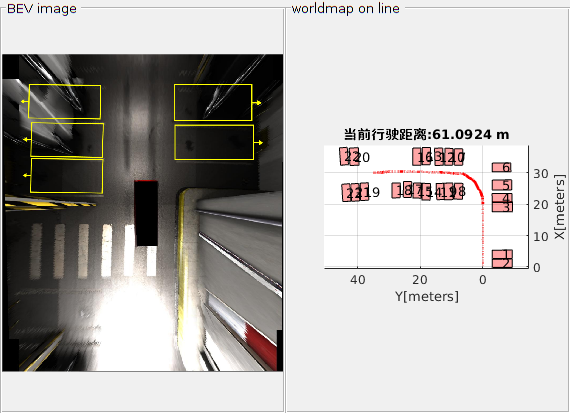

resolution = 0.0208; % 单位：米/pixel,从data/birdsEye360.mat中的front camera birdsEye变量推算
numsImg = numel(birdsEyeImgs.Files);

fig = figure(Name="map on line",NumberTitle="off");
p1 = uipanel(fig,Units="normalized",Parent=fig,Position=[0,0,0.5,1],Title="BEV image");
p2 = uipanel(fig,Units="normalized",Parent=fig,Position=[0.5,0,0.5,1],Title="worldmap on line");
ax1 = axes(p1,Position=[0,0,1,1]);
ax2 = axes(p2);
an = animatedline(ax2,Color="red",LineWidth=2);

% Set the orientation of output to upside
ax2.CameraUpVector = [1 0 0];
ax2.XLabel.String = "X[meters]";
ax2.YLabel.String = "Y[meters]";
ax2.Title.String = "当前行驶距离:0 m";
grid(ax2,"on");
axis(ax2,"equal")
hold(ax1,"on");
hold(ax2,"on");

t1 = tic;
predictions = [];% 历史所有车位世界坐标,即跟踪器，每行形如[centerX,centerY,width,height,yaw]旋转矩形表示车位
costThreshold = 2;
cumDist = 0;% 自车累计行驶距离，单位：米
preVpose = [0,0,0];% [x,y,theta]，距离单位：米，角度单位：度
for iFrame = 1:numsImg
    currImg = imread(birdsEyeImgs.Files{iFrame});
    [h,w,~] = size(currImg);

    parkingV = parkingPositions.parkingSp{iFrame};% n*5大小，[cx,cy,w,h,theta]
    numParkingV = size(parkingV,1);
    currImg = insertObjectAnnotation(currImg,"rectangle",parkingV,"",LineWidth=5);
    imshow(currImg,Parent=ax1);hold on;

    currVpose = [vehiclePoses(iFrame,[2,3])*0.01,vehiclePoses(iFrame,4)];% [x,y,theta]，距离单位：米，角度单位：度
    addpoints(an,currVpose(1),currVpose(2));

    %计算累计行驶距离
    if iFrame==1
        preVpose = currVpose;
    end
    cumDist = cumDist+sqrt((currVpose(1)-preVpose(1)).^2+(currVpose(2)-preVpose(2)).^2);
    ax2.Title.String = "当前行驶距离:"+string(cumDist)+" m";

    % parkingV转为世界坐标系的姿态表示
    if ~isempty(parkingV)
        Rframe = rotx(180)*rotz(90);
        A1 = [Rframe,zeros(3,1);
            0,0,0,1];% 图像像素坐标系到图像原点旋转中间临时坐标系
        A2 = [resolution,0,0,h/2*resolution;
            0,resolution,0,w/2*resolution;
            0,0,1,0;
            0,0,0,1];% 图像原点旋转中间临时坐标系到自车中心车辆物理坐标系
        A3 = [rotz(currVpose(3)),[currVpose(1);currVpose(2);0];
            0,0,0,1];%自车中心车辆物理坐标系到世界坐标系
        tf = A3*A2*A1;
        centerPts = [parkingV(:,1:2),zeros(numParkingV,1),ones(numParkingV,1)]';
        centerPts = tf*centerPts;
        centerPts = centerPts(1:2,:)';
        wh =  parkingV(:,3:4).*resolution;
        thetas = zeros(size(parkingV,1),1);% 当前自车中心物理坐标的绕Z轴转角
        for j = 1:size(parkingV,1)
            theta = rad2deg(rotm2eul((A3(1:3,1:3))*Rframe*rotz(parkingV(j,5))));
            thetas(j)=theta(1);
        end
        detections = [centerPts,wh,thetas];% 当前自车中心车位物理坐标，每行形如[x,y,w,h,theta],theta为度数
    else
        detections = [];
    end

    % multiple object tracker
    if ~isempty(predictions)
        if ~isempty(detections)
            predictionPts = predictions(:,1:2);
            detectionsPts = detections(:,1:2);

            cost = zeros(size(predictionPts,1),size(detectionsPts,1));
            for iTracker = 1:size(predictionPts, 1)
                diff = detectionsPts - repmat(predictionPts(iTracker,:),[size(detectionsPts,1),1]);
                cost(iTracker, :) = sqrt(sum(diff .^ 2,2));
            end
            [assignment,unassignedTracks,unassignedDetections] = ...
                assignDetectionsToTracks(cost,costThreshold);
            if ~isempty(unassignedDetections)
                newDetections = detections(unassignedDetections,:);
                predictions = [predictions;
                    newDetections];

                % visualize map,后面有时间再改为使用parkingSpace内置函数绘图(可直接生成HDmap)
                for iPark = 1:numel(unassignedDetections)
                    newPark = newDetections(iPark,:);
                    plotParkingSp(ax2,newPark,size(predictions,1)-numel(unassignedDetections)+iPark);
                end
            end
        end
    else
        predictions = detections;
        % visualize map,后面有时间再改为使用parkingSpace内置函数绘图(可直接生成HDmap)
        for iPark = 1:size(detections,1)
            newPark = detections(iPark,:);
            plotParkingSp(ax2,newPark,iPark);
        end
    end
    preVpose = currVpose;
    drawnow limitrate
    % F = getframe(fig);
    % imgName = sprintf("./results/%05d.jpg",iFrame);
    % imwrite(F.cdata,imgName);
end

t5 = toc(t1)

t5 = 359.4815

function plotParkingSp(ax,newPark,parkID)
newPark(1,[3,4])=newPark(1,[4,3]);
vertices = getVertices(newPark);
pgon = polyshape(vertices(:,1),vertices(:,2));
plot(pgon,FaceColor="red",Parent=ax);
ccpt = mean(vertices);
text(ax,ccpt(1),ccpt(2),string(parkID));
end